# MVO-31: LAB02 - Q1

Obs.: São analisadas neste programa apenas a troposfera e a tropopausa.

1a) Insira a altitude medida e obtenha os seguintes parâmetros de voo numa atmosfera ISA:

- $\rho$, densidade do ar ($kg/m3$)

- P, pressão atmosférica ($Pa$)

- T, temperatura ($K$)

h = 10000;
[rho,P,T] = atmosferaISA(h);
rho, P, T

rho = 0.4125

P = 2.6416e+04

T = 223.1500

1b) Insira a altitude medida e o $\Delta T$ e obtenha os seguintes parâmetros de voo em uma atmosfera ISA + $\Delta T$:

- $\rho$, densidade do ar ($kg/m3$)

- P, pressão atmosférica ($Pa$)

- T, temperatura ($K$)

h = 11000;
dT = 0;
[rho,P,T] = atmosferaISA(h,dT);
rho, P, T

rho = 0.3637

P = 2.2613e+04

T = 216.6500

Gerando os gráficos pedidos pelo enunciado:

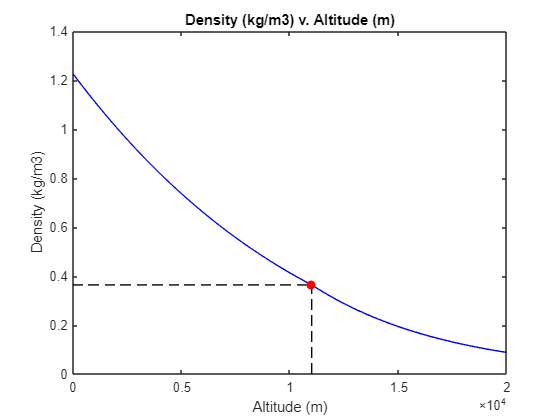

x = linspace(0, 20000, 2000);
rho1 = zeros(2000,1);
P1 = zeros(2000,1);
T1 = zeros(2000,1);
for i = 1:2000
    [rho1(i),P1(i),T1(i)] = atmosferaISA(x(i),dT);
end
plot(x,rho1,'b')
hold on
plot([0, h],[rho, rho],'k--')
plot([h, h],[0, rho],'k--')
plot(h,rho, 'r.', 'MarkerSize', 20)
title('Density (kg/m3) v. Altitude (m)')
ylabel('Density (kg/m3)')
xlabel('Altitude (m)')
hold off

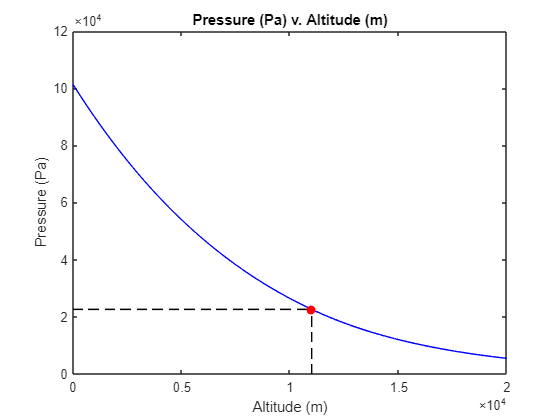


plot(x,P1,'b')
hold on
plot([0, h],[P, P],'k--')
plot([h, h],[0, P],'k--')
plot(h,P, 'r.', 'MarkerSize', 20)
title('Pressure (Pa) v. Altitude (m)')
ylabel('Pressure (Pa)')
xlabel('Altitude (m)')
hold off

1c) Insira a pressão medida, p, e obtenha a altitude Zp ($m$):

p = 101325;
Zp = altitudePressao(p);
Zp

Zp = 0

1d) Insira a pressão medida, p, e a pressão de referência, p0, e obtenha a altitude Zp ($m$):

p = 101325;
p0 = 101325;
Zp = altitudePressao(p,p0);
Zp

Zp = 0

Gerando os gráficos pedidos pelo enunciado:

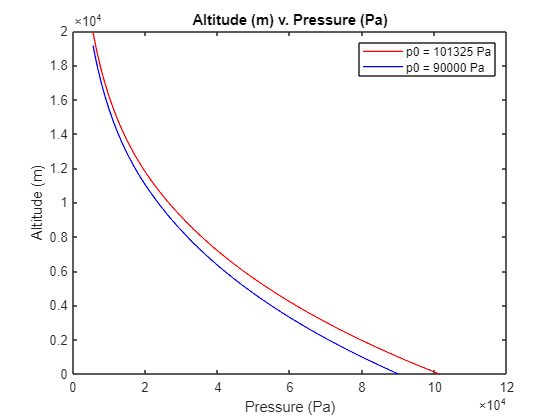

x = linspace(1e3,101325,1000);
y = linspace(1e3,90000,1000);
Zp1 = zeros(1000,1);
Zp2 = zeros(1000,1);
for i = 1:1000
    [Zp1(i)] = altitudePressao(x(i),101325);
    [Zp2(i)] = altitudePressao(y(i),90000);
end
plot(x,Zp1,'r','LineWidth',1)
xlabel('Pressure (Pa)')
ylabel('Altitude (m)')
title('Altitude (m) v. Pressure (Pa)')
hold on
plot(y,Zp2,'b','LineWidth',1)
legend('p0 = 101325 Pa', 'p0 = 90000 Pa')
hold off

function [dens, press, temp] = atmosferaISA(height, varargin)
    if nargin < 2
        dT = 0;
    else
        dT = varargin{1};
    end
    T0 = 288.15 + dT;

    P0 = 101325;
    M = 0.02897;
    R = 8.314;
    L = -0.0065;
    g = 9.81;

    if height <= 11000
        temp = T0 + L*height;
        press = P0 * (temp/T0).^(-g*M/(R*L));
    elseif height <= 20000
        temp = T0 + L*11000;
        press = P0 * (temp/T0).^(-g*M/(R*L));
        press = press * exp(-g*M*(height-11000)/(R*temp));
    else
        temp = nan;
        press = nan;
    end

    dens = (press*M)/(R*temp);
end

function [h] = altitudePressao(p, varargin)
    if nargin < 2
        p0 = 101325;
    else
        p0 = varargin{1};
    end

    T0 = 288.15;
    M = 0.02897;
    R = 8.314;
    L = -0.0065;
    g = 9.81;

    [~,p1,~] = atmosferaISA(11000);
    [~,p2,~] = atmosferaISA(20000);
    if p > p1
        h = T0/L*((p0/p)^(R*L/(g*M))-1);
    elseif p > p2
        T0 = 216.65;
        h = log(p1*p0/(p*101325)) * R*T0/(M*g)+11000;
    else
        h = nan;
    end
end